cd 'C:\Users\elite\OneDrive\Desktop\School\HRI\MiniVIE'
MiniVIE.configurePath

[MiniVIE.m] Configured MiniVIE path at: C:\Users\elite\OneDrive\Desktop\School\HRI\MiniVIE



hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Calling constructor


hMyo.initialize();

[UserConfig.m] Calling constructor with config file C:\Users\elite\OneDrive\Desktop\School\HRI\MiniVIE\user_config.xml
[UserConfig.m] myoUdpRate=200
[UserConfig.m] myoUdpPort1=10001
[UserConfig.m] myoUdpPort2=10002

Loaded pnet Version  2.0.5  2003-09-16 Copyright (C) Peter Rydesäter, Sweden, et al. , 1998 - 2003
[PnetClass] Opened pnet socket #0 at local port: 10001; Default destination: port 45001 @ 127.0.0.1
[PnetClass] Opened pnet socket #1 at local port: 10002; Default destination: port 45001 @ 127.0.0.1
[MyoUdp] UDP Data Stream 1-8 NOT Detected
[MyoUdp] UDP Data Stream 9-16 NOT Detected


[MiniVIE.m] Configured MiniVIE path at: C:\Users\elite\OneDrive\Desktop\School\HRI\MiniVIE
[UserConfig.m] userFilePrefix=USER_


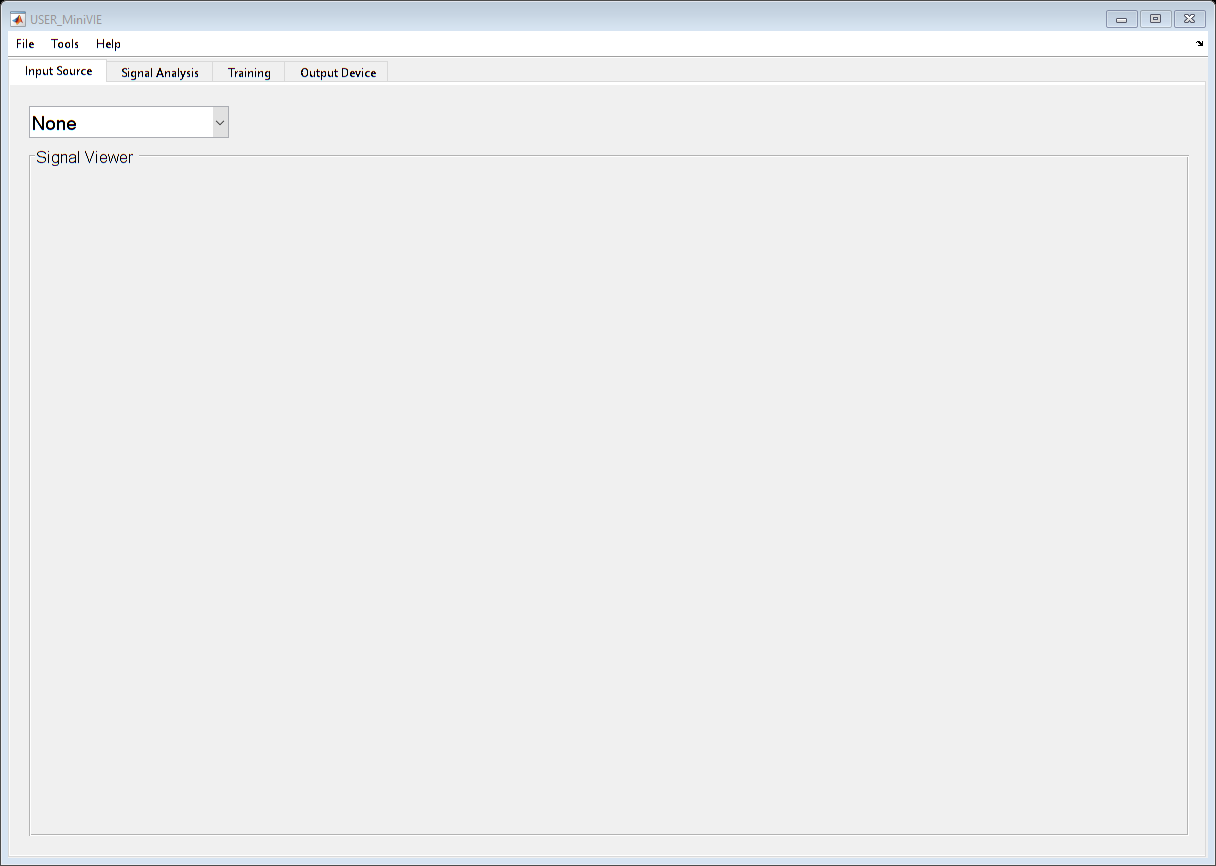

obj = MiniVIE;

% matlab.engine.shareEngine;
% matlab.engine.engineName
% 
% sprintf('Please connect to the engine using the python script')
% pause();

% CHANGE THIS TO MATCH YOUR TRAINING DATA FILE
myDataFilename = '../train.trainingData';
 
% Load training data file
hData = PatternRecognition.TrainingData();

[TrainingData] Creating Empty Training Data Object


hData.loadTrainingData(myDataFilename);

[TrainingData] Loading file: "../train.trainingData"
[TrainingData] Loading 1326 Samples
[TrainingData] Setting window size to 250.
[TrainingData] Sample rate empty.  Assuming 1000Hz


 
% Create EMG Myo Interface Object
hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Returning existing object


hMyo.initialize();

[UserConfig.m] myoUdpRate=200
[MyoUdp] UDP Comms already initialized


 
% Create LDA Classifier Object
hLda = SignalAnalysis.Lda;
hLda.initialize(hData);

[UserConfig.m] FeatureExtract.zcThreshold=0.05
[UserConfig.m] FeatureExtract.sscThreshold=0.05


hLda.train();

Training LDA with 1326 Samples (1 = 209; 2 = 249; 3 = 208; 4 = 206; 5 = 247; 6 = 207; )
Active Channels are: [ 1 2 3 4 5 6 7 8 ]


hLda.computeError();

Percent correctly classified:   95.8 %  (1326 samples)
     Wrist Abduction Class accuracy:	   81.3 % 	( 170 of  209)
     Wrist Adduction Class accuracy:	  100.0 % 	( 249 of  249)
       Wrist Flex In Class accuracy:	   97.1 % 	( 202 of  208)
    Wrist Extend Out Class accuracy:	   94.7 % 	( 195 of  206)
         Power Grasp Class accuracy:	  100.0 % 	( 247 of  247)
         No Movement Class accuracy:	  100.0 % 	( 207 of  207)


 
StartStopForm([]); % initialize a small gui utility to control a while loop

% MATLAB script to send data to Python server
% Establish connection to the Python server
host = 'localhost';
port = 65432;
client = tcpclient(host, port);

while StartStopForm
        
    % Get the appropriate number of EMG samples for the 8 myo channels
    emgData = hMyo.getData(hLda.NumSamplesPerWindow,1:8);
    
    % Extract features and classify
    features2D = hLda.extractfeatures(emgData);
    [classDecision, voteDecision] = hLda.classify(reshape(features2D',[],1));
    
    % Display the resulting class number and name
    classNames = hLda.getClassNames;
    className = classNames{classDecision};
    fprintf('Class=%2d; Class = %16s;\n',classDecision,className);
    
    % refresh the display
    drawnow;

    send_data_to_server(client, className)

    pause(2)
end

Class= 6; Class =      No Movement;
Class= 6; Class =      No Movement;
Class= 6; Class =      No Movement;
Class= 6; Class =      No Movement;
Class= 6; Class =      No Movement;
Class= 2; Class =  Wrist Adduction;
Class= 2; Class =  Wrist Adduction;
Class= 2; Class =  Wrist Adduction;
Class= 2; Class =  Wrist Adduction;
Class= 6; Class =      No Movement;
Class= 6; Class =      No Movement;
Class= 4; Class = Wrist Extend Out;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 1; Class =  Wrist Abduction;
Class= 6; Class =      No Movement;
Class= 6; Class =      No Movement;
Class= 1; Class =  Wrist Abduction;
Class= 6; Class =      No Movement;
Class= 6; Class =      No Mo


%clear client

% Function to send data to the Python server

function send_data_to_server(client, value)
    write(client, num2str(value), 'string');
end
